# 识别制动压力与减速度的系数关系

这是为了建立较为精确的纵向预测模型，用于MPC。

首先加载定义好的文件

load dlc_calibration_out2.mat dlc_out % 这是更新过的包含更多输出的一个文件

接下来要做的就是加载其中的变量并进行预处理

time_end = round(dlc_out.output_ref.Time(end))

time_end = 15

Ts = 0.01; 
time = (0:Ts:time_end)';

vx = interp1(dlc_out.output_ref.Time, ...
    dlc_out.output_ref.Data(:,13),time);
brkPres = zeros(length(time),10);
for i = 1:size(brkPres,2)
    brkPres(:,i) = interp1(dlc_out.BrkPress.Time,...
        dlc_out.BrkPress.Data(:,i),time);
end
brkPresAll = sum(brkPres,2);

然后我们先进行一个测试

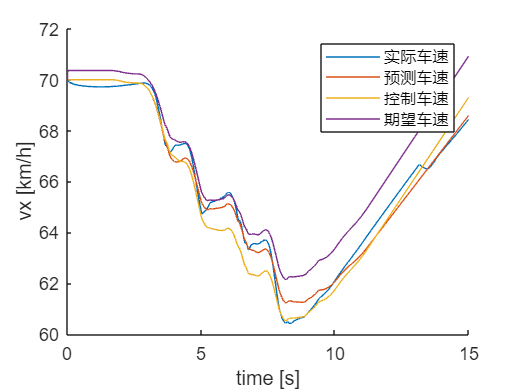

vx0 = vx(1);
coeff = -0.62; % 先给一个示例的转换系数
ax_sim0 = coeff*brkPresAll;
ax_sim = ax_sim0;
acc_idxs = time > 4;
ax_sim(acc_idxs) = ax_sim(acc_idxs) + 0.38;
vx_sim = vx0 + cumsum(ax_sim)*Ts;
ax_sim1 = coeff*brkPresAll;
v_des = 70/3.6;
delta_v_thrld = 0.35;
vx_sim1 = zeros(length(time),1);
vx_sim1(1) = vx0;
err_int = 0;
kp = 0.1;
ki = 0.02;
tau_v = 0.8;
% v_des = vx0;
v_des_add = interp1([0 3 7 15],[0 0 delta_v_thrld delta_v_thrld],time);
static_resist_acc = 0.1;
v_des_add = v_des_add + static_resist_acc;
v_dess = zeros(length(time),1);
v_dess(1) = v_des;
for i = 2:length(time)
    % err_v = v_target - vx_sim1(i-1);
    % err_int = err_int + Ts*err_v;
    % v_des = v_des + Ts*(kp*err_v + ki*err_int);
    % v_des = min(vx_sim1(i-1)+delta_v_thrld,v_des);
    vx_sim1(i) = vx_sim1(i-1) + Ts*ax_sim0(i) + Ts/tau_v*(v_des_add(i) - static_resist_acc );
    v_dess(i) = v_des_add(i) + vx_sim1(i);
end

figure
hold on
plot(time,vx*3.6)
plot(time,vx_sim*3.6)
plot(time,vx_sim1*3.6)
plot(time,v_dess*3.6)
hold off
xlabel('time [s]')
ylabel('vx [km/h]')
legend('实际车速','预测车速','控制车速','期望车速')


v_des_add0 = timeseries(v_des_add,time)

  timeseries

  常见属性:
            Name: 'unnamed'
            Time: [1501x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1501x1 double]
        DataInfo: 

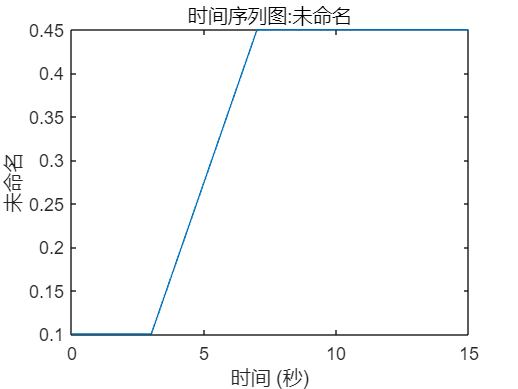

plot(v_des_add0)


$$\dot{v}_x=c_{M1} (M_{1z}^++M_{1z}^-) + c_{M2}(M_{2z}^++M_{2z}^-) - \frac{1}{\tau_v}(v_{des}-v_x )$$


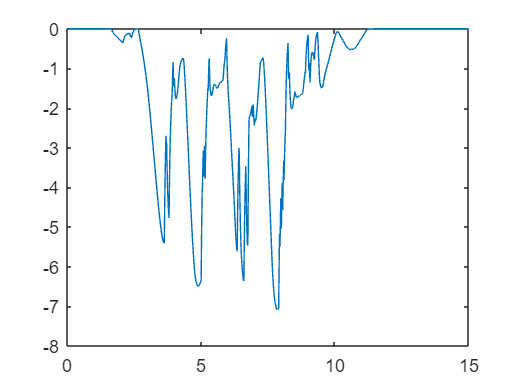

Mz_cmd = coeff*brkPresAll/0.235;
figure,plot(time,Mz_cmd)